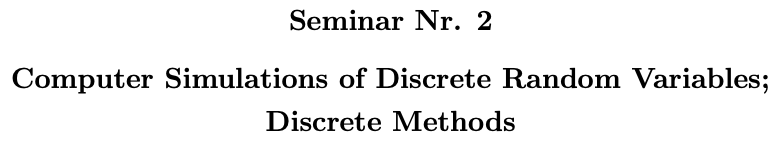

clear all;
format longg;

rand

ans =          0.882402795931734


rand(1, 20)

ans =         0.0198754228247094          0.34176488323731         0.766027445694415         0.342803701519393         0.618806404154405         0.453021162091896        0.0101626026279142         0.599081167470487         0.601568348358472         0.649417450961366         0.342720632582221         0.493299255574885          0.70177394525353          0.88780260142949        0.0550578461561846        0.0983619505457304         0.649782785472762         0.764070891236327          0.98795894159784         0.125324791415593


randn

ans =         -0.354291622942114


randn(1, 20)

ans =          0.434227622152402        -0.101478020404053          2.02876798537404         -0.36721187838228         -2.36377484799189         0.729858345361788         -1.39902075927839          1.31488703713417          0.40382537467252         -0.34416622776304        -0.980064257303274           1.8573454198871         0.309538452610443        -0.489102726025898        -0.694883298029859         -0.18039260161668          1.25628334419483          1.91074361906141        0.0271929609615699         0.427129435909406


generator = input('Generator (1-6): ');

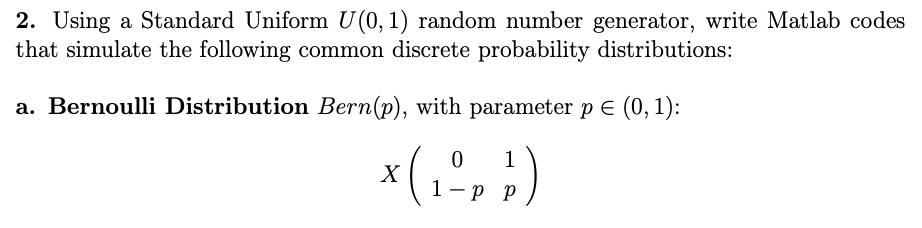

if generator==1
    p = input('p in (0,1): ');
    
    N = input('Nr of simulations: ');
    X = rand(1, N) < p

    values = unique(X);
    nX = histcounts(X, 2);
    relfreq = nX/N
end

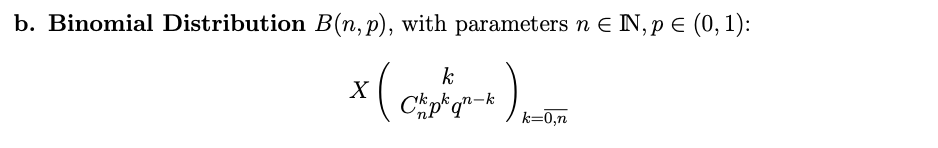

if generator==2
    p = input('p in (0,1): ');
    n = input('n (positive number): ');

    N = input('Nr of simulations: ');
    X = zeros(1, N);
    for i = 1:N
        X(i) = sum(rand(1, n) < p);
    end
    X

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X==2));
    fprintf('true probab. P(X = 2) = %1.5f\n', binopdf(2, n, p));
    fprintf('error= %e\n\n', abs(binopdf(2, n, p)) - mean(X == 2));
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X<=2));
    fprintf('true probab. P(X <= 2) = %1.5f\n', binocdf(2, n, p));
    fprintf('error= %e\n\n', abs(binocdf(2, n, p)) - mean(X <= 2));
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2));
    fprintf('true probab. P(X < 2) = %1.5f\n', binocdf(1, n, p));
    fprintf('error= %e\n\n', abs(binocdf(1, n, p)) - mean(X <= 2));
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X));
    fprintf('simulated mean E(X) = %5.5f\n', n*p);
    fprintf('error= %e\n\n', abs(n*p - mean(X)));
end

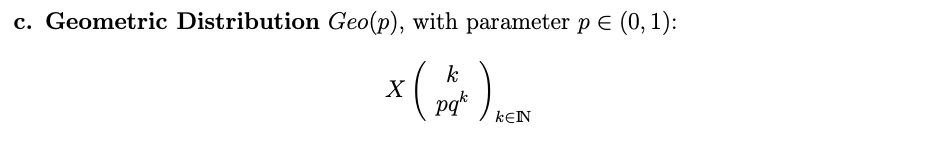

if generator==3
    p = input('p in (0,1): ');

    N = input('Nr of simulations: ');
    X = zeros(1, N);
    for i=1:N
        while rand >= p
            X(i) = X(i) + 1;
        end
    end
    X

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X==2));
    fprintf('true probab. P(X = 2) = %1.5f\n', geopdf(2, p));
    fprintf('error= %e\n\n', abs(geopdf(2, p)) - mean(X == 2));
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X<=2));
    fprintf('true probab. P(X <= 2) = %1.5f\n', geocdf(2, p));
    fprintf('error= %e\n\n', abs(geocdf(2, p)) - mean(X <= 2));
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2));
    fprintf('true probab. P(X < 2) = %1.5f\n', geocdf(1, p));
    fprintf('error= %e\n\n', abs(geocdf(1, p)) - mean(X <= 2));
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X));
    fprintf('simulated mean E(X) = %5.5f\n', (1 - p) / p);
    fprintf('error= %e\n\n', abs((1 - p) / p - mean(X)));
end

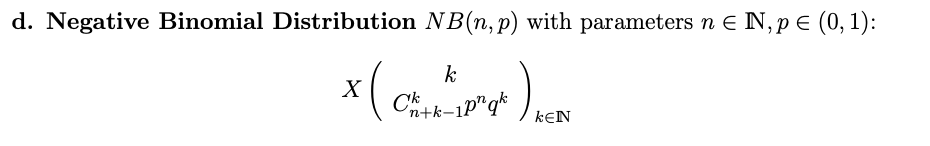

if generator==4
    p = input('p in (0,1): ');
    n = input('n (positive number): ');
    
    N = input('Nr of simulations: ');
    X = zeros(1, N);
    for i=1:N
        cnt = 0;
        while cnt < n
            if rand >= p
                X(i) = X(i) + 1;
            else
                cnt = cnt + 1;
            end
        end
    end
    X

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X==2));
    fprintf('true probab. P(X = 2) = %1.5f\n', nbinpdf(2, n, p));
    fprintf('error= %e\n\n', abs(nbinpdf(2, n, p)) - mean(X == 2));
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X<=2));
    fprintf('true probab. P(X <= 2) = %1.5f\n', nbincdf(2, n, p));
    fprintf('error= %e\n\n', abs(nbincdf(2, n, p)) - mean(X <= 2));
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2));
    fprintf('true probab. P(X < 2) = %1.5f\n', nbincdf(1, n, p));
    fprintf('error= %e\n\n', abs(nbincdf(1, n, p)) - mean(X <= 2));
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X));
    fprintf('simulated mean E(X) = %5.5f\n', n * (1 - p) / p);
    fprintf('error= %e\n\n', abs(n * (1 - p) / p - mean(X)));
end

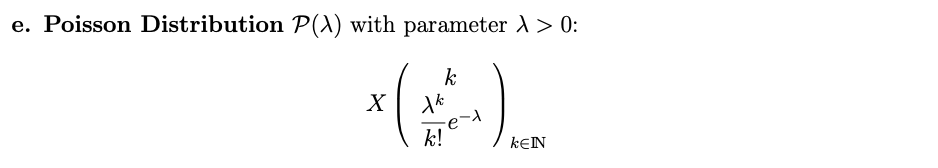

if generator==5
    L = input('lambda (positive number): ');

    N = input('Nr of simulations: ');
    X = zeros(1, N);
    for i=1:N
        cnt = exp(-L);
        U = rand;
        while U >= cnt
            X(i) = X(i) + 1;
            cnt = cnt + exp(-L) * L^X(i) / factorial(X(i));
        end
    end
    X

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X==2));
    fprintf('true probab. P(X = 2) = %1.5f\n', poisspdf(2, L));
    fprintf('error= %e\n\n', abs(poisspdf(2, L)) - mean(X == 2));
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X<=2));
    fprintf('true probab. P(X <= 2) = %1.5f\n', poisscdf(2, L));
    fprintf('error= %e\n\n', abs(poisscdf(2, L)) - mean(X <= 2));
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2));
    fprintf('true probab. P(X < 2) = %1.5f\n', poisscdf(1, L));
    fprintf('error= %e\n\n', abs(poisscdf(1, L)) - mean(X <= 2));
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X));
    fprintf('simulated mean E(X) = %5.5f\n', L);
    fprintf('error= %e\n\n', abs(L - mean(X)));
end

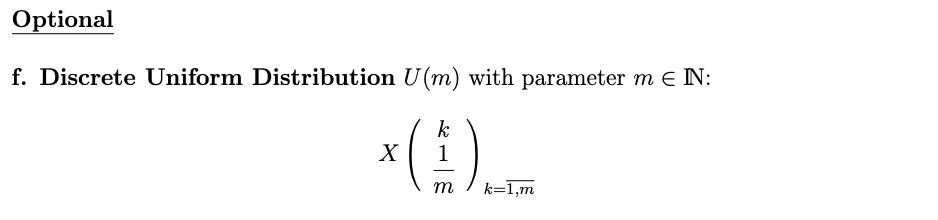

if generator==6
    m = input('m (positive integer): ');

    N = input('Nr of simulations: ');
    X = ceil(rand(1, N) * m)

    fprintf('simulated probab. P(X = 2) = %1.5f\n', mean(X==2));
    fprintf('true probab. P(X = 2) = %1.5f\n', unidpdf(2, m));
    fprintf('error= %e\n\n', abs(unidpdf(2, m)) - mean(X == 2));
    
    fprintf('simulated probab. P(X <= 2) = %1.5f\n', mean(X<=2));
    fprintf('true probab. P(X <= 2) = %1.5f\n', unidcdf(2, m));
    fprintf('error= %e\n\n', abs(unidcdf(2, m)) - mean(X <= 2));
    
    fprintf('simulated probab. P(X < 2) = %1.5f\n', mean(X < 2));
    fprintf('true probab. P(X < 2) = %1.5f\n', unidcdf(1, m));
    fprintf('error= %e\n\n', abs(unidcdf(1, m)) - mean(X <= 2));
    
    fprintf('simulated mean E(X) = %5.5f\n', mean(X));
    fprintf('simulated mean E(X) = %5.5f\n', (m + 1) / 2);
    fprintf('error= %e\n\n', abs((m + 1) / 2 - mean(X)));
end

X =      8     1     6     1     5     5     1     1    10     6     4     4     2     2     4     4     8     5     5     2     9     7     9     7    10    10     3     7     8     5     9     2     2     1     2     6     6     4     4     1     9     7     5     3     9     9     9     5    10     9


simulated probab. P(X = 2) = 0.09800


true probab. P(X = 2) = 0.10000


error= 2.000000e-03



simulated probab. P(X <= 2) = 0.20500


true probab. P(X <= 2) = 0.20000


error= -5.000000e-03



simulated probab. P(X < 2) = 0.10700


true probab. P(X < 2) = 0.10000


error= -1.050000e-01



simulated mean E(X) = 5.51100


simulated mean E(X) = 5.50000


error= 1.100000e-02

